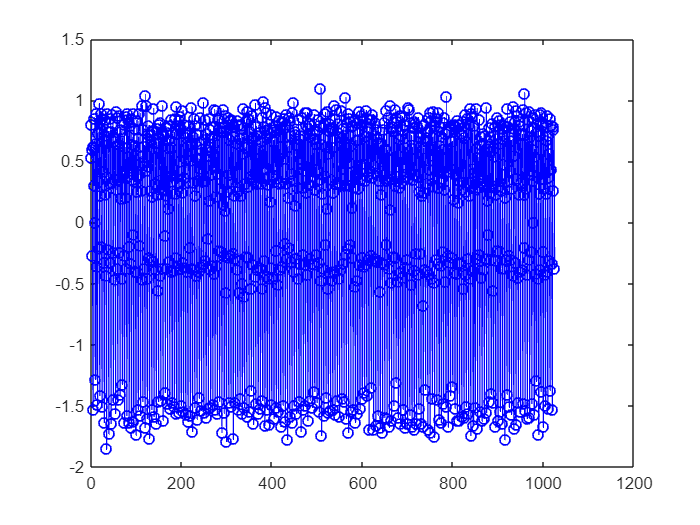

% FFT Length = 1024 

%Stimulus

N = 1024;
Fs = 50e6;F1 = 10e6;F2 = 20e6;
mode = 2; i_ready = 1;rst = 0;

clear("genframe2Sample");
clear("fftchecker");
clear("dutFFT");

y_fixed = zeros(1,N,'like',fi(0,1,16,13));


for i = 1:N
 [y_fixed(i),~,~,ref_frame] = genframe2Sample(N, Fs,F1,F2,mode,i_ready,rst);
end

plot(ref_frame,'bo-', 'LineWidth', 1);

% DUT FFT

Yf = zeros(1,3*N);
validOut = false(1,3*N);
for loop = 1:1:3*N
    if (mod(loop, N) == 0)
        i = N;
    else
        i = mod(loop, N);
    end
    [Yf(loop),validOut(loop)] = dutFFT(complex(y_fixed(i)),(loop <= N),N);
end

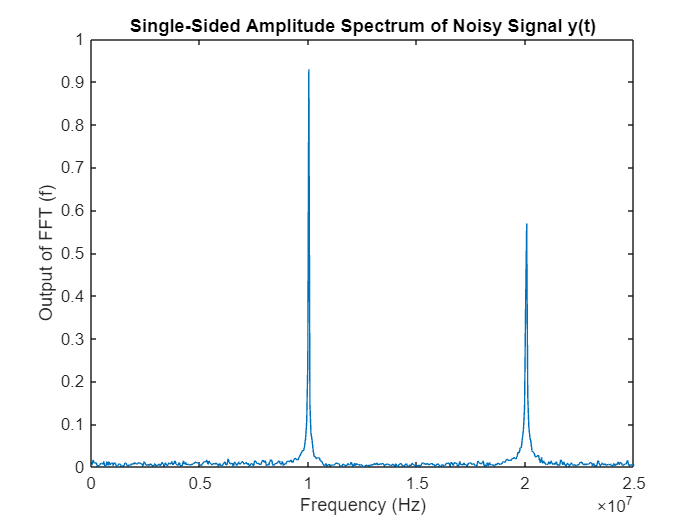

Yf = Yf(validOut == 1);
Yr =  bitrevorder(Yf);
plot(Fs/2*linspace(0,1,N/2), 2*abs(Yr(1:N/2)/N))
title('Single-Sided Amplitude Spectrum of Noisy Signal y(t)')
xlabel('Frequency (Hz)')
ylabel('Output of FFT (f)')

% Checker Compare against reference 

Threshold = 10e3;

 dut_re = real(Yr);
 dut_im = imag(Yr);
for i = 1:N+2
    if (i<=N)
        valid = 1;j=i;
    else
        valid = 0;
    end
    [~,~,o_f1_exp,o_f1_dut] = fftchecker(ref_frame,dut_re(j),dut_im(j),valid,N,Fs,Threshold) ; 
end

REF_CALC freq_1 = 10009765.625000 
REF_CALC freq_2 = 20019531.250000 
DUT_CALC freq_1 = 10009765.625000 
DUT_CALC freq_2 = 20019531.250000 
